# Voting Record - PCA

## 1.

Load `voting.mat`. This file contains a matrix representing the congressional voting record of 435 U.S. representatives on 16 key issues, and a categorical array with their political party affiliation (“Democrat” or “Republican”). The votes are recorded as “-1” for a negative vote, “1” for a positive vote, and “0” for a neutral or no vote.

load voting.mat

## 2.

Calculate the principal components of the voting records.

[coeff,score,~,~,expl] = pca(vote)

coeff =    -0.1917    0.1992   -0.1386    0.7355   -0.4379    0.1272   -0.0907    0.1129    0.2890   -0.0639    0.1061   -0.1574   -0.0578    0.0589   -0.0092   -0.0624
    0.0521    0.6010    0.1626    0.2498    0.6247    0.0335    0.0999    0.1726   -0.0799   -0.2571   -0.0604   -0.0780    0.1086   -0.1027   -0.1073   -0.0007
   -0.2944    0.0817    0.1968    0.0306   -0.0295   -0.2454   -0.3855   -0.1412   -0.0106    0.0639    0.1201    0.3776    0.6325    0.1474   -0.1373   -0.1885
    0.3141   -0.1303   -0.1279    0.0738    0.1072    0.0903    0.2243    0.2380    0.0473   -0.0636   -0.0740    0.1532    0.1037    0.7761    0.0566   -0.2906
    0.3367    0.0497   -0.0087    0.0677   -0.1100    0.0711   -0.2521    0.1866   -0.0096    0.0621   -0.1133    0.2316    0.0777    0.1345   -0.2684    0.7729
    0.2564    0.0815    0.2986   -0.1263   -0.0686   -0.3733   -0.4197   -0.1309    0.1339   -0.4084    0.2155   -0.2039   -0.3826    0.2297   -0.0784   -0.0848
   -0.2933   -0.1887   -0.

score =     3.4488    0.1160    1.0953    0.1812    0.5880    0.2362    0.4553    0.6925   -0.3556    0.3131    0.2196   -0.3678    0.0247   -0.0615   -0.0712   -0.0917
    3.5883    0.6724   -0.9806   -0.1127    0.7991   -0.2502    0.1141   -0.0053   -0.0918   -0.1717    0.0602   -0.1551    0.1202   -0.1239   -0.0228   -0.0808
    1.8918    2.5369    0.3315    0.0941   -0.7034   -0.1723   -0.6519   -1.1627   -0.0173    0.1585   -1.0517    0.8872    0.4850    0.1551   -0.1076   -0.2719
    0.6639    2.4723    0.6946   -0.8001    0.2666   -0.6411   -0.8544   -0.5801   -1.0875    1.6023    0.5158    0.4125   -0.4379   -0.2592   -0.0830   -0.5538
    0.9842    2.5068    0.4943   -0.0855   -0.9906    0.0363   -1.5007    0.9032    1.1059    0.5778   -0.0304   -0.3527    0.7701   -0.7623   -0.3119   -0.1312
    1.2173    1.3078   -0.0851   -0.8838    0.9041   -0.2795   -2.5060    0.3761    0.3152    0.6922   -0.8555   -0.0623    0.5597   -0.9005   -0.0170   -0.0736
    2.1569    0.7945   -0.

expl =    47.3962
    8.8450
    7.0673
    5.4903
    4.7554
    3.8510
    3.3186
    3.2032
    3.0099
    2.6996


## 3.

Make a Pareto chart of the variance explained by the principal components.

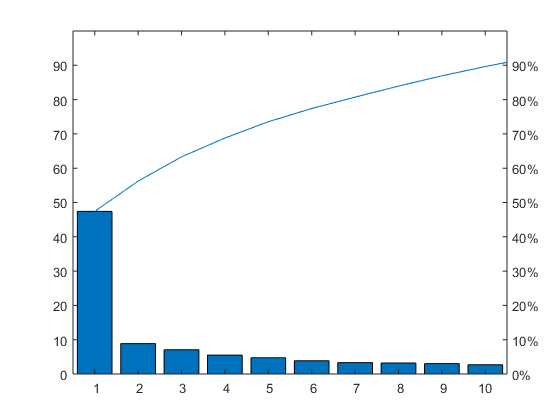

pareto(expl)

## 4.

Use `biplot` to plot the representation of the 16 voting issues in terms of the first three principal components. You can use the cell array of text `issues` to label the points.

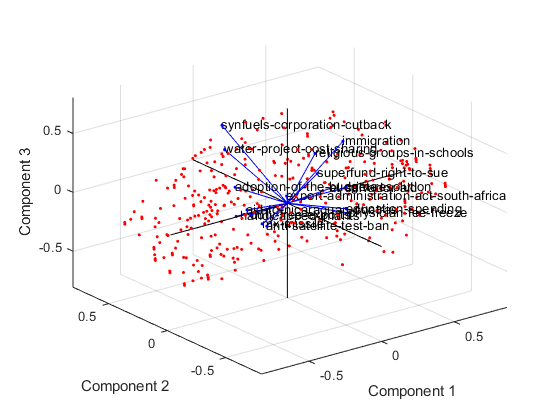

biplot(coeff(:,1:3),'Scores',score(:,1:3),'VarLabels',issues)

## 5.

Use `heatmap` and the cell array of text `issues `to generate and label a heatmap chart showing the factor loadings of the PCA coefficients.

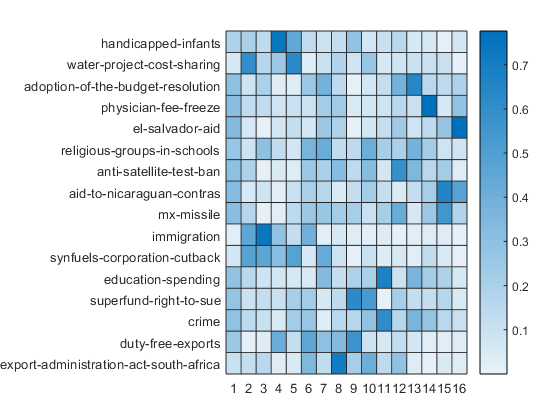

h = heatmap(abs(coeff));
h.YData = issues;

## 6.

Make a scatter plot of the first two components of the scores, grouped by political party affiliation. What do you notice?

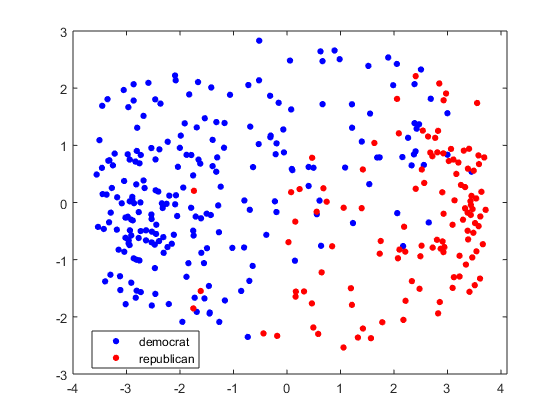

gscatter(score(:,1),score(:,2),party,'br')